# 3.4.2 算术运算

MATLAB`的基本算术运算符有：＋`(`加`)`、－`(`减`)`、`*(`乘`)`、`/(`右除`)`、`\(`左除`)`、`^(`乘方`)`和'` (`转置`)`，下面我们一一进行介绍。`

`首先是``矩阵的加法``。在线性代数中，只有两个大小完全相同的矩阵才可以进行相加，而在`MATLAB`中，只要两个矩阵的大小兼容，就能够进行计算。`

**以下是一些具有兼容大小的标量、向量和矩阵的组合：**

- **两个大小完全相同的输入。**

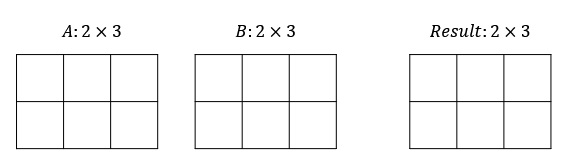

A = randi(10,2,3)

A =      9     2     7
    10    10     1


B = randi(10,2,3)

B =      3    10     2
     6    10    10


A + B

ans =     12    12     9
    16    20    11


- **一个输入是标量。**

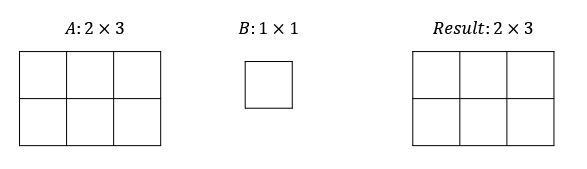

A = randi(10,2,3)

A =     10     9     5
     5     2    10


B = randi(10,1)

B = 8

A + B

ans =     18    17    13
    13    10    18


- **一个输入是矩阵，另一个输入是具有相同行数的列向量。**

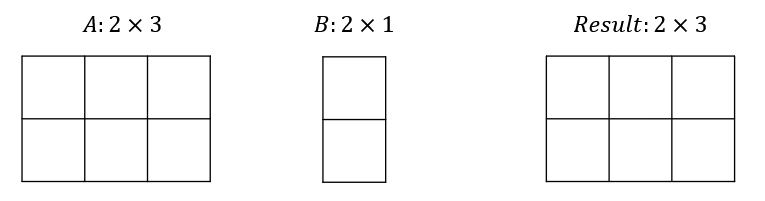

A = randi(10,2,3)

A =     10     1    10
     7     9     7


B = randi(10,2,1)

B =      8
     8


A + B

ans =     18     9    18
    15    17    15


- **一个输入是矩阵，另一个输入是具有相同列数的行向量。**

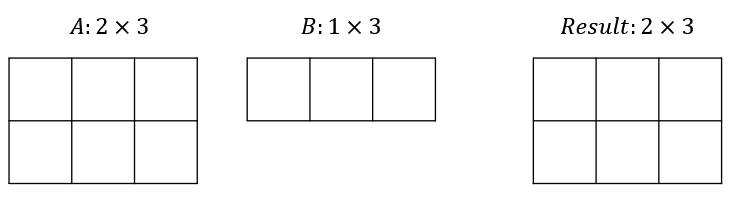

A = randi(10,2,3)

A =      4     2     1
     7     8     3


B = randi(10,1,3)

B =      1     1     9


A + B

ans =      5     3    10
     8     9    12


- **一个输入是列向量，另一个输入是行向量。**

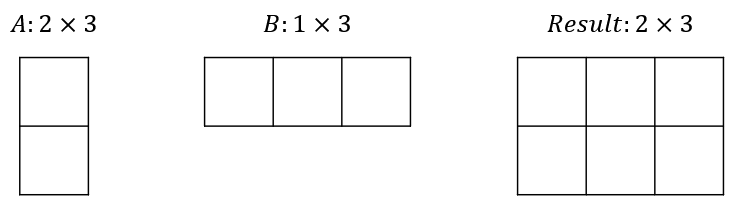

A = randi(10,2,1)

A =      7
     4


B = randi(10,1,3)

B =     10     1     5


A + B

ans =     17     8    12
    14     5     9


总结：

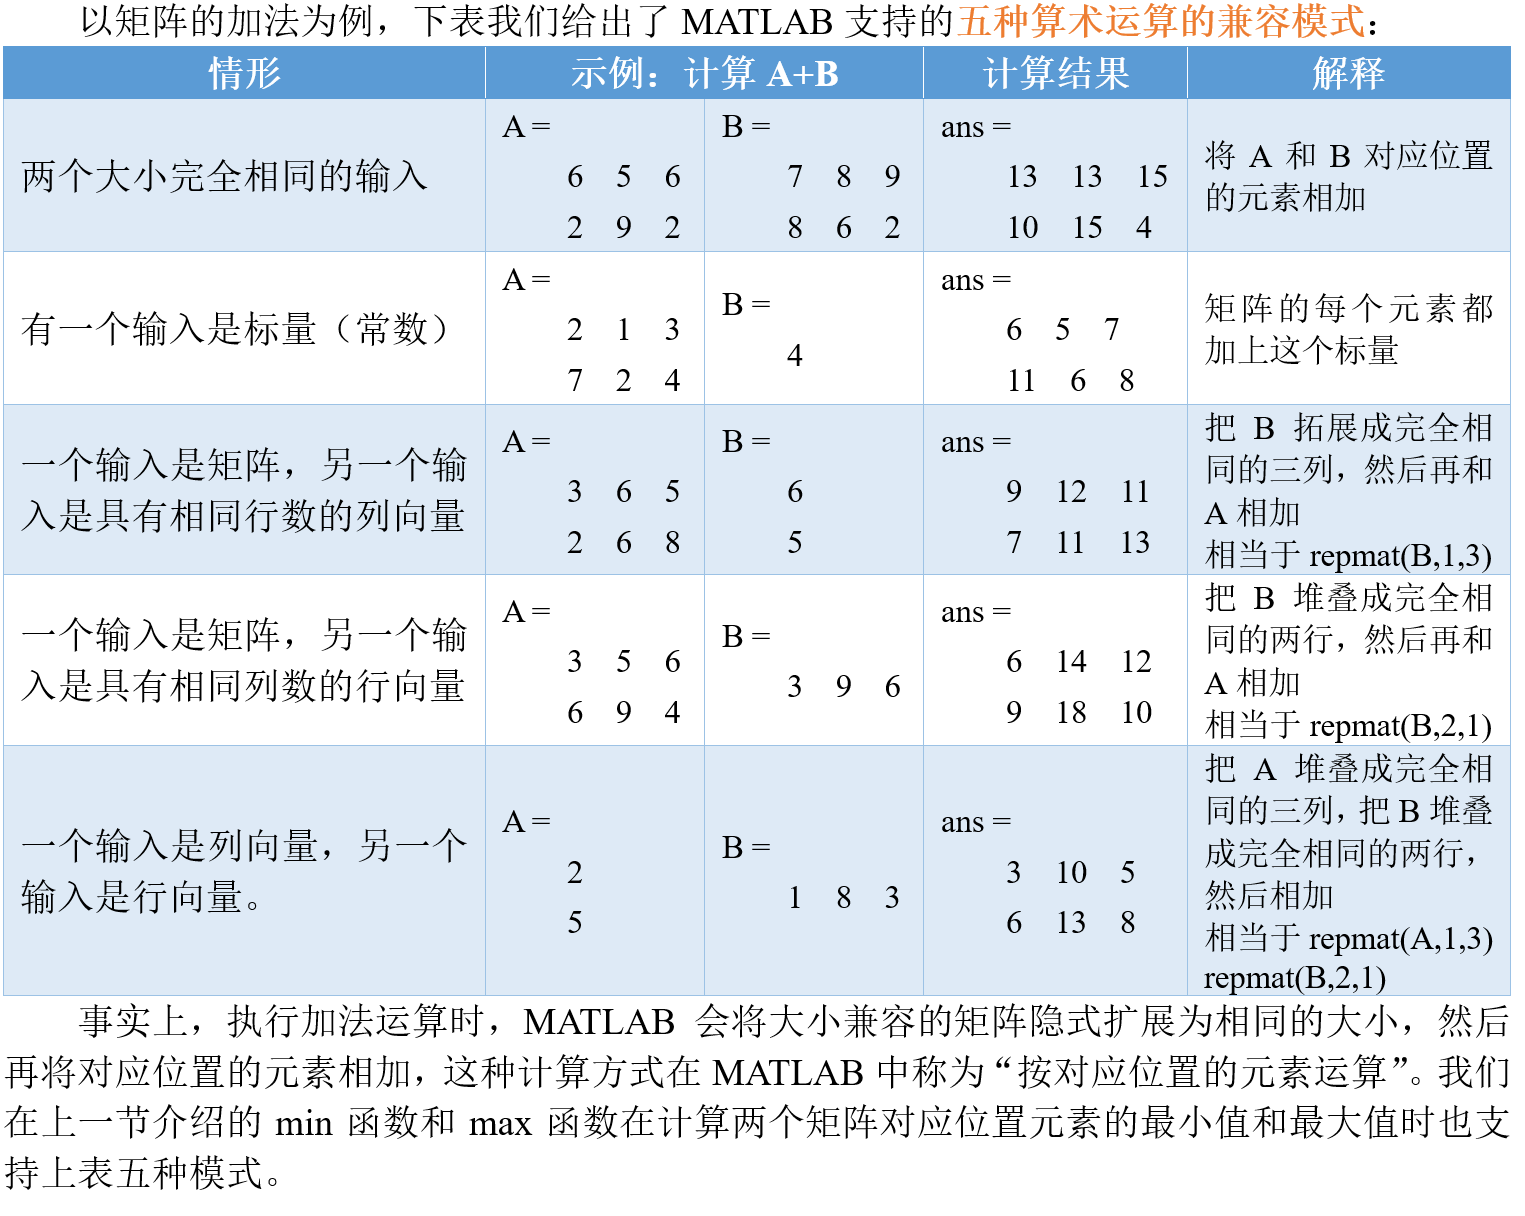

A = randi(10,4,3)

A =      4     5     8
     8     5     3
     8     7     7
     2     8     7


B = randi(10,1,3)

B =      2     2     5


min(A,B)

ans =      2     2     5
     2     2     3
     2     2     5
     2     2     5


事实上，执行加法运算时，MATLAB会将大小兼容的矩阵隐式扩展为相同的大小，然后再将对应位置的元素相加，这种计算方式在MATLAB中称为**“按对应位置的元素运算”。**

类似的，**矩阵的减法**也满足这种计算规则，大家可以自行测试。

A = randi(10,2,3)

A =     10     6     8
     4     3     3


B = randi(10,2,3)

B =      6     9     6
     7    10     2


A - B

ans =      4    -3     2
    -3    -7     1


A = randi(10,1,3)

A =      2     3     9


B = randi(10,2,3)

B =      3     3     4
     9    10     2


A - B

ans =     -1     0     5
    -7    -7     7


A = randi(10,1,3)

A =      3     7     5


B = randi(10,2,1)

B =      4
     9


A - B

ans =     -1     3     1
    -6    -2    -4


**矩阵的乘法**则有所不同，在MATLAB中，矩阵的乘法分为两种：

一种是线性代数中定义的矩阵的乘法，使用的运算符号是乘号“*”，例如矩阵A*B，矩阵的乘法必须要满足前面矩阵A的列数和后面矩阵B的行数相等；

A = randi(10,2,3)

A =      4     9     7
    10     6     6


B = randi(10,3,1)

B =      3
     4
     5


A * B

ans =     83
    84


A = randi(10,1,3)

A =      3     9     2


B = randi(10,3,1)

B =      3
     2
     3


A * B

ans = 33

另一种是“按对应位置的元素运算”的乘法，使用的运算符号是点乘 “.*” ，例如A.*B，这时A和B的大小只需要满足上方表格介绍的五种兼容模式。

A = randi(10,2,3)

A =      5    10     2
     4     5    10


B = randi(10,2,3)

B =     10     2     5
     5     3     6


A .* B

ans =     50    20    10
    20    15    60


A = randi(10,2,3)

A =      3     8     2
     7     3     3


B = randi(10,1,3)

B =      4     5     6


A .* B

ans =     12    40    12
    28    15    18


`特别的，如果一个矩阵和常数相乘，那么使用乘号“`*`”和点乘“`.*`”得到的结果相同。`

x = randi(10,5)

x =      1     8    10     7     1
     3     5     6     7     9
     9     6     6     4    10
     1     3     3     4     8
    10     5     5    10     1


y = 3;
x * y 

ans =      3    24    30    21     3
     9    15    18    21    27
    27    18    18    12    30
     3     9     9    12    24
    30    15    15    30     3


x.* y 

ans =      3    24    30    21     3
     9    15    18    21    27
    27    18    18    12    30
     3     9     9    12    24
    30    15    15    30     3


`下面我们再来介绍``矩阵的除法``。事实上，在我们学的线性代数中，矩阵并不能进行除法的运算，但`MATLAB`中定义了矩阵的除法的计算规则。`

`在`MATLAB`中，除号有两种，``分别是 `**/(**`右除`**) **`和 `**\(**`左除`**)：**

（可以把这个符号想象成一个梯子，梯子靠在哪边墙上就是哪边的除法）

`这两个符号用的非常的少，大家不用可以去记，需要用时再来查询即可。`

`（1）命令“`x = B/A`”表示对线性方程组`x*A = B`求解`x`；`

A = [2,8,2;
     5,-4,8;
     6,4,0];
B = [18,60,-6];
x = B / A   % [5 -2 3]

x =     5.0000   -2.0000    3.0000


% 验算下：x*A是否等于B
x * A

ans =    18.0000   60.0000   -6.0000


`（2）命令“`x = A\B`”则表示对线性方程组`A*x = B`求解`x`。`

A = [1 5 8;
     2,4,9;
     3,0,2];
B = [10;
     4;
     -1];
x = A\B  % [1;5;-2]

x =     1.0000
    5.0000
   -2.0000


% 验算下：A*x是否等于B
A * x

ans =     10
     4
    -1


`用的更多的是对矩阵进行点除的操作，即将两个矩阵按对应位置的元素做除法。`

`其中命令“`A ./ B`”表示用`A`的每个元素除以`B`的对应元素，`A`和`B`的大小必须兼容；`

`命令“`A .\ B`”则表示用`B`的每个元素除以`A`的对应元素，这个用法不太符合我们的习惯。`

`因此，大家只需要掌握点右除“`A ./ B`”的用法即可。`

A = randi([0,10],3,2)

A =      6     6
     9     2
     8     2


B = randi([0,10],3,2)

B =      9     1
     0    10
     5     7


A ./ B  % 点右除

ans =     0.6667    6.0000
       Inf    0.2000
    1.6000    0.2857


1 ./ A  % 对A中每个元素计算倒数

ans =     0.1667    0.1667
    0.1111    0.5000
    0.1250    0.5000


`特别地，如果`B`是标量，那么`A./B`的结果和`A/B`的结果相同。`

A = randi(10,3)

A =      6     7     6
     5     1     1
     1     1     9


B = 3;
A./B

ans =     2.0000    2.3333    2.0000
    1.6667    0.3333    0.3333
    0.3333    0.3333    3.0000


A / B

ans =     2.0000    2.3333    2.0000
    1.6667    0.3333    0.3333
    0.3333    0.3333    3.0000


`矩阵的乘方``也有两种用法，分别是“`^`”和“`.^`”。`

`其中，“`^`”表示矩阵的幂运算，例如`A`是一个方阵，那么`A ^ 3`等价于`A*A*A`；`

`“`.^`”表示对矩阵中的每一个元素分别进行乘方计算，例如`A .^ 0.5`表示对矩阵`A`中的每一个元素开根号。`

A = randi([0,10],2,2)

A =      7     1
     1    10


A ^ 3

ans =          367         220
         220        1027


A * A * A

ans =          367         220
         220        1027


在网上看到了一个有趣的例子，我们验证下：

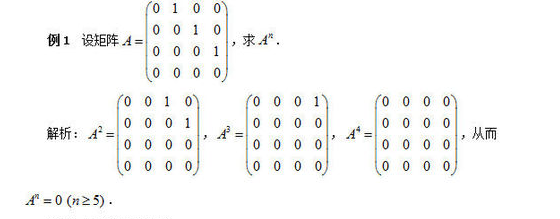

A = diag(ones(1,3),1)

A =      0     1     0     0
     0     0     1     0
     0     0     0     1
     0     0     0     0


A ^ 2  % A * A

ans =      0     0     1     0
     0     0     0     1
     0     0     0     0
     0     0     0     0


A ^ 3  % A * A * A

ans =      0     0     0     1
     0     0     0     0
     0     0     0     0
     0     0     0     0


A ^ 4 % A * A * A * A

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


`“`**.^**`”表示对矩阵中的每一个元素分别进行乘方计算`

A = randi(10,3,4)

A =      2     9     4     2
     1     7     5     9
     6     2    10     7


A .^ 2  % 每个元素求平方，等价于 A .* A

ans =      4    81    16     4
     1    49    25    81
    36     4   100    49


 A .* A

ans =      4    81    16     4
     1    49    25    81
    36     4   100    49


A .^ 0.5   % 每个元素开根号

ans =     1.4142    3.0000    2.0000    1.4142
    1.0000    2.6458    2.2361    3.0000
    2.4495    1.4142    3.1623    2.6458


sqrt(A)

ans =     1.4142    3.0000    2.0000    1.4142
    1.0000    2.6458    2.2361    3.0000
    2.4495    1.4142    3.1623    2.6458


A .^ (-1)   % 每个元素求倒数，等价于 1./ A 

ans =     0.5000    0.1111    0.2500    0.5000
    1.0000    0.1429    0.2000    0.1111
    0.1667    0.5000    0.1000    0.1429


1./ A 

ans =     0.5000    0.1111    0.2500    0.5000
    1.0000    0.1429    0.2000    0.1111
    0.1667    0.5000    0.1000    0.1429


**拓展：计算逆矩阵**

`如果`A`是一个可逆的方阵，那么`A^(-1)`可用来计算`A`的逆矩阵（`inverse matrix`）。另外，`MATLAB`中的`inv`函数也可以计算逆矩阵，它们的计算结果相同。`

% 只有方阵才有逆矩阵的概念
A = [1 2 3;
    2 2 1;
    3 4 3]

A =      1     2     3
     2     2     1
     3     4     3


B1 = A ^ (-1)

B1 =     1.0000    3.0000   -2.0000
   -1.5000   -3.0000    2.5000
    1.0000    1.0000   -1.0000


B2 = inv(A)

B2 =     1.0000    3.0000   -2.0000
   -1.5000   -3.0000    2.5000
    1.0000    1.0000   -1.0000


`根据线性代数中逆矩阵的定义，互为逆矩阵的两个矩阵的乘积为单位矩阵（主对角线为`1`，其余位置为`0`的方阵）`

% format long g
B1*A

ans =     1.0000    0.0000         0
   -0.0000    1.0000   -0.0000
    0.0000         0    1.0000


format short

理想情况下，B1*A将生成单位矩阵。

**由于 MATLAB使用浮点数计算矩阵的逆存在一定的误差，因此，实际上 B1*A接近但不完全等于单位矩阵。**

`最后我们再来介绍``矩阵的转置``运算，矩阵的转置符号为英文的``单``引号：“ ’ ”，它也可以在前面加上点变成“ `.`’ ”，两者的区别在于对矩阵中复数的处理，使用“ ’ ”会在转置的同时将复数变为共轭复数，使用“`.`’``”则会保持原来的复数。`

format short
A = [ 3     1+3i;
      2     5;
      4-2i  6];
A'

ans =    3.0000 + 0.0000i   2.0000 + 0.0000i   4.0000 + 2.0000i
   1.0000 - 3.0000i   5.0000 + 0.0000i   6.0000 + 0.0000i


A.'

ans =    3.0000 + 0.0000i   2.0000 + 0.0000i   4.0000 - 2.0000i
   1.0000 + 3.0000i   5.0000 + 0.0000i   6.0000 + 0.0000i


`当然，通常情况下我们的矩阵中全是实数，那么使用“``’``”和“`.`’``”的效果相同。`

A = randi(10,3,4)

A =      4     5     3     3
     2     2     4     3
     5     6     6     7


A'

ans =      4     2     5
     5     2     6
     3     4     6
     3     3     7


A.'

ans =      4     2     5
     5     2     6
     3     4     6
     3     3     7


## **练习**

**（1）计算用来评价预测效果好坏的一些指标 **

假设真实值是向量$y=\left\lbrack \begin{array}{cccc}
y_1  & y_2  & \cdots  & y_n 
\end{array}\right\rbrack$, 拟合值或预测值是向量$\hat{y} =\left\lbrack \begin{array}{cccc}
\hat{y_1 }  & \hat{y_2 }  & \cdots  & \hat{y_n } 
\end{array}\right\rbrack$

**SSE** 误差(或残差)平方和  （Sum of Squares due to Error ）


$$SSE\,\,=\,\,\sum_{i=1}^n{\left( y_i-\hat{y}_i \right) ^2}$$


范围[0,+∞)，当预测值与真实值完全吻合时等于0。误差越大，该值越大。

它的量纲是原来数据量纲的平方。

y = [100 102 108 117 135 178 198 241 290 349];
y_hat = [93 108 118 117 141 170 196 249 296 359];
y-y_hat

ans =      7    -6   -10     0    -6     8     2    -8    -6   -10


(y-y_hat).^2

ans =     49    36   100     0    36    64     4    64    36   100


SSE = sum( (y-y_hat).^2 )

SSE = 489

**MSE **均方误差（Mean Square Error）

就是SSE除了一个n


$$MSE\,\,=\,\,\frac{1}{n}\sum_{i=1}^n{\left( y_i-\hat{y}_i \right) ^2}$$


范围[0,+∞)，当预测值与真实值完全吻合时等于0。误差越大，该值越大。

它的量纲是原来数据量纲的平方。

y = [100 102 108 117 135 178 198 241 290 349];
y_hat = [93 108 118 117 141 170 196 249 296 359];
n = length(y);
MSE = 1/n*(sum( (y-y_hat).^2 ))

MSE = 48.9000

**RMSE:  **均方根误差（Root Mean Square Error）

其实就是MSE加了个根号


$$RMSE\,\,=\,\,\sqrt{\frac{1}{n}\sum_{i=1}^n{\left( y_i-\hat{y}_i \right) ^2}}$$


范围[0,+∞)，当预测值与真实值完全吻合时等于0。误差越大，该值越大。

它的量纲和原来数据的量纲相同。

y = [100 102 108 117 135 178 198 241 290 349];
y_hat = [93 108 118 117 141 170 196 249 296 359];
n = length(y);
RMSE = sqrt( 1/n*(sum((y-y_hat).^2)) )

RMSE = 6.9929

**MAE:** 平均绝对误差（Mean Absolute Error）


$$MAE\,\,=\,\,\frac{1}{n}\sum_{i=1}^n{\left| y_i-\hat{y}_i \right|}$$


范围[0,+∞)，当预测值与真实值完全吻合时等于0。误差越大，该值越大。

它的量纲和原来数据的量纲相同。

y = [100 102 108 117 135 178 198 241 290 349];
y_hat = [93 108 118 117 141 170 196 249 296 359];
n = length(y);
y-y_hat

ans =      7    -6   -10     0    -6     8     2    -8    -6   -10


abs(y-y_hat) 

ans =      7     6    10     0     6     8     2     8     6    10


MAE = mean(abs(y-y_hat) )

MAE = 6.3000

MAE = 1/n*( sum( abs(y-y_hat) ) )

MAE = 6.3000

**MAPE: **平均绝对百分比误差（Mean Absolute Percentage Error）


$$MAPE\,\,=\,\,\frac{1}{n}\sum_{i=1}^n{\left| \frac{y_i-\hat{y}_i}{y_i} \right|}$$$$


该公式通常将值乘以100，以百分比形式表示数字。

范围[0,+∞)，当预测值与真实值完全吻合时等于0。

可以看到，MAPE跟MAE很像，就是多了个分母。

注意：当真实值有数据等于0时，存在分母为0的问题，该公式不可用！

y = [100 102 108 117 135 178 198 241 290 349];
y_hat = [93 108 118 117 141 170 196 249 296 359];
n = length(y);
fz = y-y_hat;  % 分子
MAPE = mean(abs(fz ./ y))

MAPE = 0.0403

MAPE = 1/n*(sum(abs(fz ./ y)))

MAPE = 0.0403

我们可以将这个数乘以100，那么它的单位为%

MAPE = 1/n*(sum(abs(fz ./ y))) * 100

MAPE = 4.0344

**SMAPE：**对称平均绝对百分比误差（Symmetric Mean Absolute Percentage Error）


$$SMAPE\,\,=\,\,\frac{100\%}{n}\sum_{i=1}^n{\frac{\left| y_i-\hat{y}_i \right|}{\left( \left| y_i \right|+\left| \hat{y}_i \right| \right) /2}}$$


它的范围是0％到200％，当预测值与真实值完全吻合时等于0。

注：有些地方定义的SMAPE的分母没有加绝对值，这时候SMAPE可能为负数。

y = [100 102 108 117 135 178 198 241 290 349];
y_hat = [93 108 118 117 141 170 196 249 296 359];
n = length(y);
fz = abs(y-y_hat)  % 分子

fz =      7     6    10     0     6     8     2     8     6    10


fm = (abs(y)+abs(y_hat))/2  % 分母

fm =    96.5000  105.0000  113.0000  117.0000  138.0000  174.0000  197.0000  245.0000  293.0000  354.0000


fz./ fm

ans =     0.0725    0.0571    0.0885         0    0.0435    0.0460    0.0102    0.0327    0.0205    0.0282


SMAPE = 1/n*(sum(fz./ fm ))

SMAPE = 0.0399

我们可以将这个数乘以100，那么它的单位为%

SMAPE = 1/n*(sum(fz./ fm )) * 100

SMAPE = 3.9916

$R^2$**：**决定系数、可决系数、R方、拟合优度（Coefficient of determination）

注意：如果使用的是线性回归模型，那么下面两种计算R方的公式都可以使用，且此时R方的范围是[0,1]

$$$
R^2=1-\frac{\sum{\left( y-\hat{y} \right) ^2}}{\sum{\left( y-\bar{y} \right) ^2}}
\\
R^2=\frac{\sum{\left( \hat{y}-\bar{y} \right) ^2}}{\sum{\left( y-\bar{y} \right) ^2}} \\
式中\bar{y} 是y的均值
$$
$y：原始值；y_hat：均值；y_^：拟合值或预测值

如果使用的是非线性回归模型，那么R方使用的是第一种定义方法！且此时R方的范围是($-\infty ,1$].

越接近于1，证明预测效果越好

（线性回归中，两种方法算出来的R方一定相等。非线性回归中只能使用第一种方法计算，第二种算出来的结果是错的！）

y = [100 102 108 117 135 178 198 241 290 349];
y_hat = [93 108 118 117 141 170 196 249 296 359];
% 使用第1种方法计算
fz = sum((y - y_hat).^2); % 分子
mean(y)

ans = 181.8000

fm = sum((y - mean(y)).^2); % 分母 
R2 = 1 - fz/fm  

R2 = 0.9928

% 使用第2种方法计算
fz = sum((y_hat - mean(y)).^2); % 分子
fm = sum((y - mean(y)).^2); % 分母 
R2 = fz/fm  

R2 = 1.0618

两种方法不一致，说明我们的模型是非线性的模型，只能使用第一种方法计算！

**上面介绍的这些指标都有其优点和缺点，感兴趣的同学可以在网上搜索更多相关的内容学习。**

**（2）计算优化算法中常见的测试函数**

**维基百科上关于测试函数的定义：**

**In applied mathematics, test functions, known as artificial landscapes, are useful to evaluate characteristics of optimization algorithms, such as:**

- **Velocity of convergence.**

- **Precision.**

- **Robustness.**

- **General performance.**

**翻译成中文就是：**

**在应用数学中，测试函数可用于评估优化算法的特性，例如:**

- **收敛速度。**

- **精度。**

- **鲁棒性。**

- **一般性能。**

**用来测试算法效率的函数叫做测试函数。当你提出了一种新的优化算法（用来求解一个函数的最值问题）后，你需要和别人之前提出的算法来进行对比，看你的算法有没有提高。**

**下面我们一起来计算四种常见的测试函数：**

**Sphere函数 **


$$f\left( x \right) =\sum_{i=1}^n{x_{i}^{2}}
$$$$


x = 1:10

x =      1     2     3     4     5     6     7     8     9    10


x.^2

ans =      1     4     9    16    25    36    49    64    81   100


y = sum(x.^2)  % x.^2 表示x中每一个元素分别计算平方

y = 385

**Rastrigin函数**


$$f\left( x \right) =\sum_{i=1}^n{\left( x_{i}^{2}-10\cos \left( 2\pi x_i \right) +10 \right)}$$


x = 1:10;
x.^2

ans =      1     4     9    16    25    36    49    64    81   100


-10*cos(2*pi*x)

ans =    -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


y = sum(x.^2-10*cos(2*pi*x)+10)

y = 385

这里有个易错点：cos(2*pi*x)里面的乘号不能省略哦

**Griewank函数**


$$f\left( x \right) =\frac{1}{4000}\sum_{i=1}^n{x_{i}^{2}}-\prod_{i=1}^n{\cos}\left( \frac{x_i}{\sqrt{i}} \right) +1$$


x = 1:10;
1/4000 * sum(x.^2)

ans = 0.0963

n = length(x)

n = 10

sqrt(1:n)

ans =     1.0000    1.4142    1.7321    2.0000    2.2361    2.4495    2.6458    2.8284    3.0000    3.1623


x./sqrt(1:n)

ans =     1.0000    1.4142    1.7321    2.0000    2.2361    2.4495    2.6458    2.8284    3.0000    3.1623


cos(x./sqrt(1:n))

ans =     0.5403    0.1559   -0.1606   -0.4161   -0.6173   -0.7699   -0.8796   -0.9514   -0.9900   -0.9998


prod(cos(x./sqrt(1:n)))

ans = 0.0022

n = length(x);
y = 1/4000*sum(x.*x)-prod(cos(x./sqrt(1:n))) + 1

y = 1.0940

这里的难点在于中间那一项，其中$\frac{x_i}{\sqrt{i}}$(i=1,2,…,n)构成的向量可以直接用x./sqrt(1:n)表示。

sqrt(1:n)

ans =     1.0000    1.4142    1.7321    2.0000    2.2361    2.4495    2.6458    2.8284    3.0000    3.1623


x./sqrt(1:n)  % 要用点除哦，对应元素相除

ans =     1.0000    1.4142    1.7321    2.0000    2.2361    2.4495    2.6458    2.8284    3.0000    3.1623


**Rosenbrock函数**


$$f\left( x \right) =\sum_{i=1}^{n-1}{\left[ 100\left( x_{i+1}-x_{i}^{2} \right) ^2+\left( x_i-1 \right) ^2 \right]}$$


x = 1:10;
tem1 = x(1:end-1)

tem1 =      1     2     3     4     5     6     7     8     9


tem2 = x(2:end)

tem2 =      2     3     4     5     6     7     8     9    10


y = sum(100 * (tem2-tem1.^2).^2 + (tem1-1).^2)

y = 1109904

这里我生成了两个临时变量，分别是tem1和tem2

另外，这里求平方时，只能用 "点乘方.^" ，不能写成^

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)